clc
clear
close all
rng(100)

%cd("/MATLAB Drive/Q4/Radar_Project")
load('test_SVD.mat')
load('labels_SVD.mat')

Y = string(size(labels))';

for i = 1:length(labels)
    Y(i) = labels(i);
end
Y1 = Y(1:240);
Y2 = Y(253:672);
Y=[Y1;Y2];
X1= All_result(1:240,:);
X2=All_result(253:672,:);
X = vertcat(X1, X2);
%X = All_result;   
Y = cellstr(Y);
X = zscore(X)

X =    -0.0447   -1.8199   -3.8743    6.9536    1.8683   -1.2840   -3.6044    3.9273   -2.0721    2.3076   -0.4848   -2.1890   -1.8081   -1.4322
   -1.2565   -0.5599    1.3753    0.4898   -0.5350   -1.2370   -0.4314   -0.6551   -0.2098    0.7015   -0.1196    0.2231    0.5133    0.4745
    1.2597    1.5210   -0.9794    0.0759   -1.0307    0.1947    1.8671    1.7937   -0.0209    0.3851   -0.3051   -0.3468    0.2936    0.3861
   -0.6590   -0.0914    0.1946   -0.6552   -0.4578   -0.9826   -1.2421    0.8370    0.6232   -0.2604   -0.0848    0.9548    0.0830    0.4431
    0.9721    1.2667   -0.5422   -0.6871   -1.3119    0.1269    0.5370   -0.6771    1.1564   -0.6538    0.0945    0.0288    0.6390    1.1211
   -0.3263    0.0080   -0.2156   -0.4238   -0.6045   -1.0677   -0.2758   -1.0589    1.3529   -1.1056   -0.4935    1.4476    0.5079    1.4646
   -0.1062    0.5751   -0.3460   -0.0334   -1.5838   -0.3469   -0.3322   -0.4008    1.2873   -0.9450   -0.7726    0.1865    0.7884    1.0039
   -0.197

%Perform PCA

[coeff, score] = pca(X);
X=X*coeff;

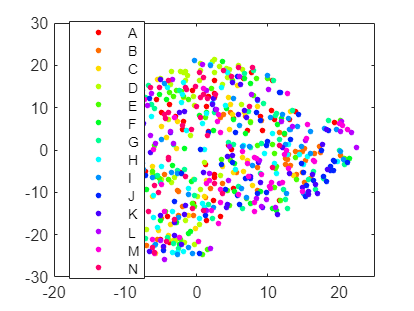

g_view = tsne(X(:,:));
gscatter(g_view(:,1),g_view(:,2),Y)

% Split the data into training and test sets
trainRatio = 0.7;  % 70% for training, 30% for testing
numSamples = size(X, 1);
numTrain = round(trainRatio * numSamples);
numTest = numSamples - numTrain;

% Shuffle the data and labels using the same indices
shuffledIndices = randperm(numSamples);
X = X(shuffledIndices, :);
X = zscore(X);          %standardization
Y = Y(shuffledIndices);


%Split the data into training and test sets
XTrain = X(1:numTrain, :);
YTrain = Y(1:numTrain);
XTest = X(numTrain+1:end, :);
YTest = Y(numTrain+1:end);

Feature Selection

[idx,scores] = fscchi2(X,Y);
find(isinf(scores))


ans =

  空的 1×0 double 行向量



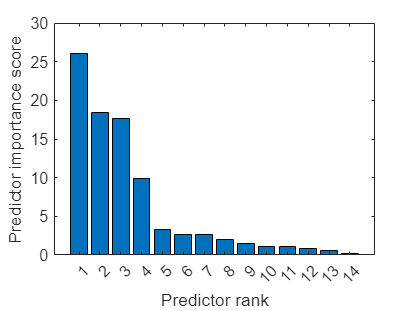

bar(scores(idx))
xlabel('Predictor rank')
ylabel('Predictor importance score')

X = X(:,:);
XTrain = X(1:numTrain, :);
YTrain = Y(1:numTrain);
XTest = X(numTrain+1:end, :);
YTest = Y(numTrain+1:end);

YTest

YTest = 198×1 cell 数组
    {'K'}
    {'C'}
    {'E'}
    {'N'}
    {'M'}
    {'H'}
    {'H'}
    {'M'}
    {'A'}
    {'E'}
    {'E'}
    {'B'}
    {'E'}
    {'B'}
    {'A'}
    {'F'}
    {'K'}
    {'J'}
    {'K'}
    {'N'}
    {'K'}
    {'B'}
    {'L'}
    {'C'}
    {'C'}
    {'I'}
    {'L'}
    {'F'}
    {'A'}
    {'H'}


Train the KNN model

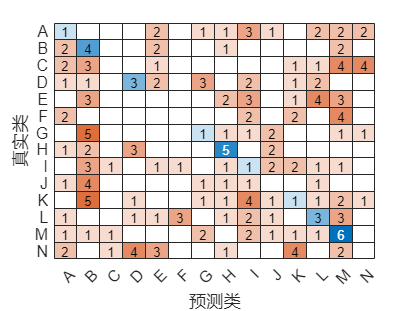

k = 20;  % Number of neighbors to consider
MyModel_KNN = fitcknn(XTrain, YTrain, 'NumNeighbors', k);

YPred_KNN = predict(MyModel_KNN, XTest);

% Evaluate the accuracy of the model
confusionchart(YTest, YPred_KNN)

CM_KNN = confusionmat(YTest, YPred_KNN);

accuracy_KNN = acc(CM_KNN);

Accuracy: 12.63%


Accuracy: 11.62%
Accuracy: 9.09%
Accuracy: 10.61%
Accuracy: 13.13%
Accuracy: 15.66%
Accuracy: 15.66%
Accuracy: 15.15%
Accuracy: 15.66%
Accuracy: 16.16%
Accuracy: 16.16%
Accuracy: 16.16%
Accuracy: 15.66%
Accuracy: 14.14%
Accuracy: 13.13%
Accuracy: 16.16%
Accuracy: 14.65%
Accuracy: 12.63%
Accuracy: 10.61%
Accuracy: 10.61%
Accuracy: 12.63%
Accuracy: 13.13%
Accuracy: 13.13%
Accuracy: 12.12%
Accuracy: 14.65%
Accuracy: 11.62%
Accuracy: 13.13%
Accuracy: 13.13%
Accuracy: 13.64%
Accuracy: 12.63%
Accuracy: 11.11%
Accuracy: 12.63%
Accuracy: 12.63%
Accuracy: 14.14%
Accuracy: 13.64%
Accuracy: 12.63%
Accuracy: 12.63%
Accuracy: 14.14%
Accuracy: 12.63%
Accuracy: 11.62%
Accuracy: 14.14%
Accuracy: 13.64%
Accuracy: 15.66%
Accuracy: 14.14%
Accuracy: 15.15%
Accuracy: 15.66%
Accuracy: 15.66%
Accuracy: 15.15%
Accuracy: 13.13%
Accuracy: 15.15%


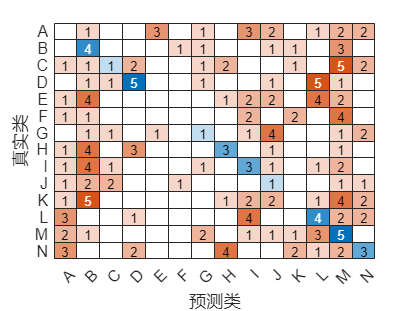

Accuracy: 15.15%


accuracy_KNN = zeros(50,1);
for i = 1:50
    k = i;  % Number of neighbors to consider
    MyModel_KNN = fitcknn(XTrain, YTrain, 'NumNeighbors', k);
    YPred_KNN = predict(MyModel_KNN, XTest);
    
    % Evaluate the accuracy of the model
    confusionchart(YTest, YPred_KNN)
    CM_KNN = confusionmat(YTest, YPred_KNN);
    
    accuracy_KNN(i) = acc(CM_KNN);
    % fprintf('Accuracy: %.2f%%\n', accuracy_KNN(i) * 100);
end


[~,idx_max]=max(accuracy_KNN);
MyModel_KNN_new = fitcknn(XTrain, YTrain, 'NumNeighbors', idx_max);
YPred_KNN = predict(MyModel_KNN, XTest);

confusionchart(YTest, YPred_KNN)

CM_KNN = confusionmat(YTest, YPred_KNN);

accuracy_KNN(i) = acc(CM_KNN);

Accuracy: 15.15%


fprintf('Accuracy: %.2f%%\n', accuracy_KNN(i) * 100);

Accuracy: 15.15%


Accuracy: 21.97%
Accuracy: 20.45%
Accuracy: 34.09%
Accuracy: 31.82%


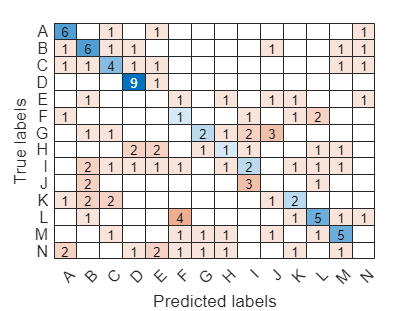

Accuracy: 32.58%


k = 5;


indices = crossvalind('Kfold', size(X, 1), k);

for i = 1:k
   
    test_indices = (indices == i);
    train_indices = ~test_indices;
    
   
    X_train = X(train_indices, :);
    Y_train = Y(train_indices, :);
    X_test = X(test_indices, :);
    Y_test = Y(test_indices, :);
    
    
 
    MyModel_KNN = fitcknn(XTrain, YTrain, 'NumNeighbors', idx_max);
   
    Y_pred = predict(MyModel_KNN, X_test);
    
    
    confusionchart(Y_test, Y_pred)
    CM_SVM = confusionmat(Y_test, Y_pred);
    xlabel('Predicted labels')
    ylabel('True labels')
    accuracy = acc(CM_SVM);
end

avg_accuracy = mean(accuracy);


Train the SVM model

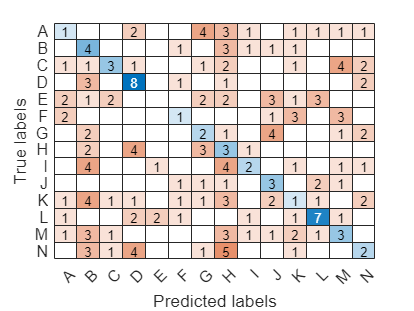

%svmModel_SVM = fitcecoc(XTrain, YTrain); %SVM with multical classes

template = templateSVM();
svmModel_SVM = fitcecoc(XTrain, YTrain, 'Learners', template); % SVM with RBF kernel -> Accuracy: 11.31%%
YPred_SVM = predict(svmModel_SVM, XTest);

% Evaluate the accuracy of the model
confusionchart(YTest, YPred_SVM)
CM_SVM = confusionmat(YTest, YPred_SVM);
    xlabel('Predicted labels')
    ylabel('True labels')

accuracy_SVM = acc(CM_SVM);

Accuracy: 20.20%


function accu = acc(MyCM)

% Calculate accuracy
correctPredictions = sum(diag(MyCM));
totalSamples = sum(MyCM(:));
accu = correctPredictions / totalSamples;

% Display accuracy
fprintf('Accuracy: %.2f%%\n', accu * 100);
end